download of the dataset and verification of no correlation between the different features through a scatter plot of every feature with the others (could have done a confusion matrix too)

clear,close all;
data=load("airfoil_self_noise.dat");
% for i=1:5
%     for j=2:6
%         figure;
%         scatter(data(:,i),data(:,j));
%         title([num2str(i) "and" num2str(j)]);
%     end
% end

let's see for clustering, here the elbow method, we can see the stagnation at 13 clusters

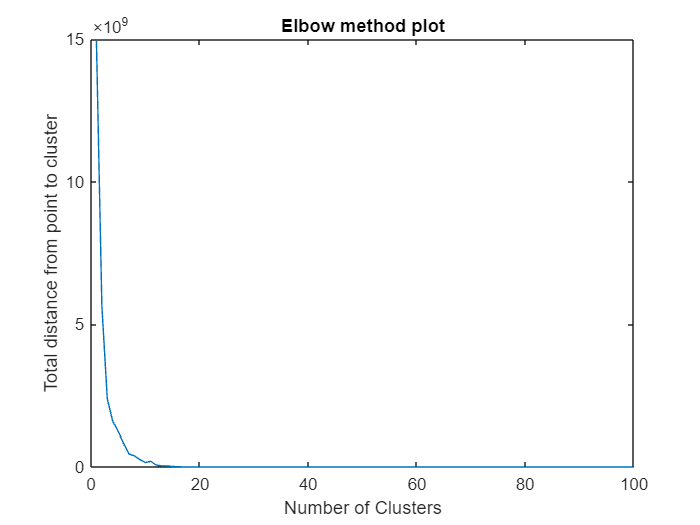

totaldistance=zeros(1,100);
for i=1:100
    [Kid,Kcenters,Kdsum]=kmeans(data,i);
    % Kdsum=Kdsum/max(Kdsum);
    for k=1:length(Kdsum)
        totaldistance(1,i)=totaldistance(1,i)+Kdsum(k);     
    end
end
figure;
plot(totaldistance);
title('Elbow method plot');
xlabel('Number of Clusters');
ylabel('Total distance from point to cluster')

max(data(:,1)) 

ans = 20000

min(data(:,1))

ans = 200

max(data(:,2)) 

ans = 22.2000

min(data(:,2))

ans = 0

max(data(:,3)) 

ans = 0.3048

min(data(:,3))

ans = 0.0254

max(data(:,4)) 

ans = 71.3000

min(data(:,4))

ans = 31.7000

max(data(:,5))

ans = 0.0584

min(data(:,5))

ans = 4.0068e-04


parfor i=1:100
    [c,u,obj]=fcm(data,i);
    % Kdsum=Kdsum/max(Kdsum);
    cost(i)=min(obj);
end

Iteration count = 1, obj. fcn = 1.24846e+09
Iteration count = 2, obj. fcn = 9.27902e+08
Iteration count = 3, obj. fcn = 8.87132e+08
Iteration count = 4, obj. fcn = 7.13756e+08
Iteration count = 5, obj. fcn = 4.59824e+08
Iteration count = 6, obj. fcn = 2.64202e+08
Iteration count = 7, obj. fcn = 1.35466e+08
Iteration count = 8, obj. fcn = 9.81147e+07
Iteration count = 9, obj. fcn = 5.04057e+07
Iteration count = 10, obj. fcn = 3.74205e+07
Iteration count = 11, obj. fcn = 2.96706e+07
Iteration count = 12, obj. fcn = 1.22853e+07
Iteration count = 13, obj. fcn = 1.21015e+07
Iteration count = 14, obj. fcn = 1.20974e+07
Iteration count = 15, obj. fcn = 1.20944e+07
Iteration count = 16, obj. fcn = 1.20922e+07
Iteration count = 17, obj. fcn = 1.20903e+07
Iteration count = 18, obj. fcn = 1.20889e+07
Iteration count = 19, obj. fcn = 1.20878e+07
Iteration count = 20, obj. fcn = 1.20869e+07
Iteration count = 21, obj. fcn = 1.20862e+07
Iteration count = 22, obj. fcn = 1.20856e+07
Iteration count = 1

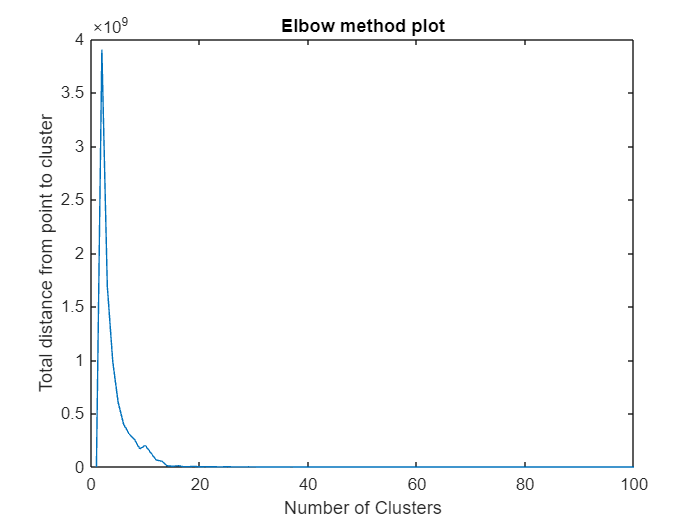

figure;
plot(cost);
title('Elbow method plot');
xlabel('Number of Clusters');
ylabel('Total distance from point to cluster')

Normalization of the dataset for smoother processing

for input=1:5
    data(:,input)=(data(:,input)-min(data(:,input)))/(max(data(:,input))-min(data(:,input)));
end
train=randperm(1503,ceil(1503*0.8));
points=[];
for p=1:length(data)
    if isempty(find(train==p))
        points=[points p];
    end
end

datatrain=data(train,:);
datatest=data(points,:);

% fcm clustering
[clusters, U,fobj] = fcm(data(:, 1:end-1), 15);  % run a fcm clustering Exclude output column

Iteration count = 1, obj. fcn = 55.3752
Iteration count = 2, obj. fcn = 41.4963
Iteration count = 3, obj. fcn = 41.4782
Iteration count = 4, obj. fcn = 41.4375
Iteration count = 5, obj. fcn = 41.3446
Iteration count = 6, obj. fcn = 41.1435
Iteration count = 7, obj. fcn = 40.7582
Iteration count = 8, obj. fcn = 40.1516
Iteration count = 9, obj. fcn = 39.3531
Iteration count = 10, obj. fcn = 38.4031
Iteration count = 11, obj. fcn = 37.456
Iteration count = 12, obj. fcn = 36.419
Iteration count = 13, obj. fcn = 35.2009
Iteration count = 14, obj. fcn = 34.1401
Iteration count = 15, obj. fcn = 33.3101
Iteration count = 16, obj. fcn = 32.7621
Iteration count = 17, obj. fcn = 32.444
Iteration count = 18, obj. fcn = 32.1305
Iteration count = 19, obj. fcn = 31.8139
Iteration count = 20, obj. fcn = 31.6224
Iteration count = 21, obj. fcn = 31.5439
Iteration count = 22, obj. fcn = 31.4977
Iteration count = 23, obj. fcn = 31.4558
Iteration count = 24, obj. fcn = 31.4097
Iteration count = 25, obj. f

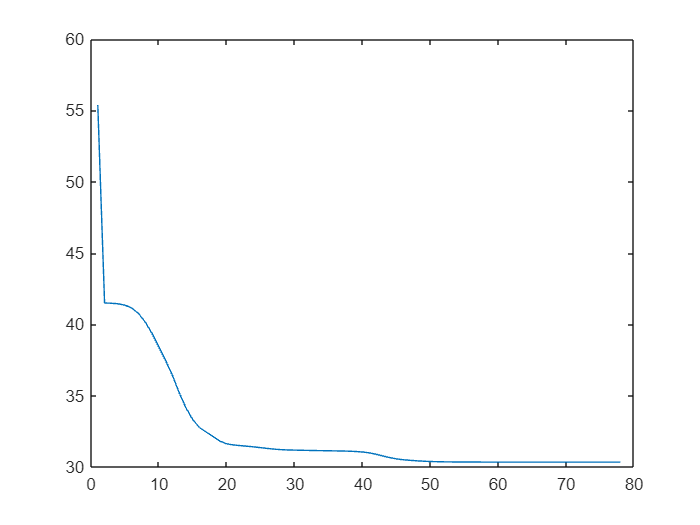

figure;
plot(fobj);

Now let's begin the inference system and problem definition

We have a 5 inputs 1 output FIs that will be trained using a cascading GA and then for the inference, we will use 2 systems, a TSK 1st order and a TSK 0 order to compare efficiency.

% GA parameters
% stochastic rates :
selection_rate=0.01;
elitism_rate=0.001;
mutation_rate=0.3;

% generational parameters
Popsize=200;
maxgen=200;

Let's initialize both the TSKs

%TSK0_pop=initTSK0(Popsize);
cluster_pop=initfcm(Popsize,clusters);
% TSK1_pop=initTSK1(Popsize);
% TSK1_pop=TSK1_pop';
%TSK0_pop=TSK0_pop';
parfor i=1:Popsize
    fit0(i)=fitfcm(cluster_pop{i},datatrain,clusters);
end

now let's do the optimization

bestfit=[];
for gen=1:maxgen
    
    mutation_rate=max(0.5,1-gen/maxgen);
    [num_elites,pool] = selection(cluster_pop, fit0, selection_rate,Popsize,elitism_rate);
    cluster_pop = reproduction(pool, mutation_rate, Popsize,num_elites,clusters);
    
    % now the new fitness
    bestfit(gen)=min(fit0); % store best fitness
    parfor i=1:Popsize
        newfit(i)=fitfcm(cluster_pop{i},datatrain,clusters);
    end
    fit0=newfit;
    disp(["gen" gen ", best fit = " bestfit(gen) "avg=" bestfit(gen)/length(datatrain)])
end

    "gen"    "1"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "2"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "3"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "4"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "5"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "6"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "7"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "8"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "9"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "10"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "11"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "12"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "13"    ", best fit = "    "8044.4759"    "avg="    "6.687"

    "gen"    "14"    ", best fit = "    "8044.4

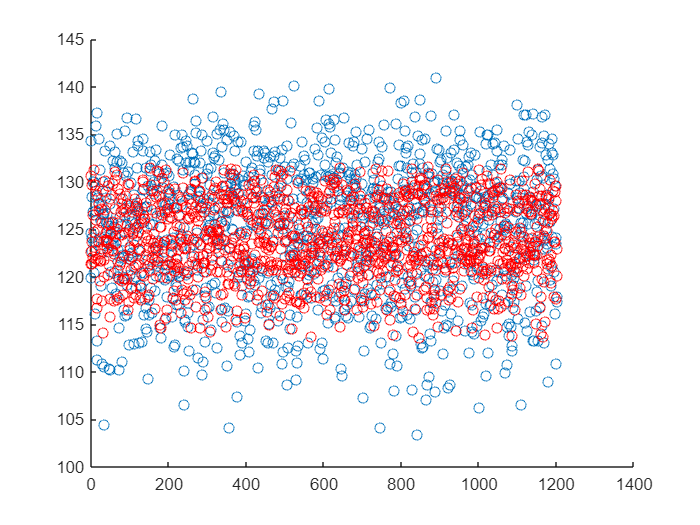

out = 6.2046e+03

[~, sorted_idx] = sort(fit0, 'ascend');
out=visucluster(cluster_pop{sorted_idx(1)},datatrain,clusters)

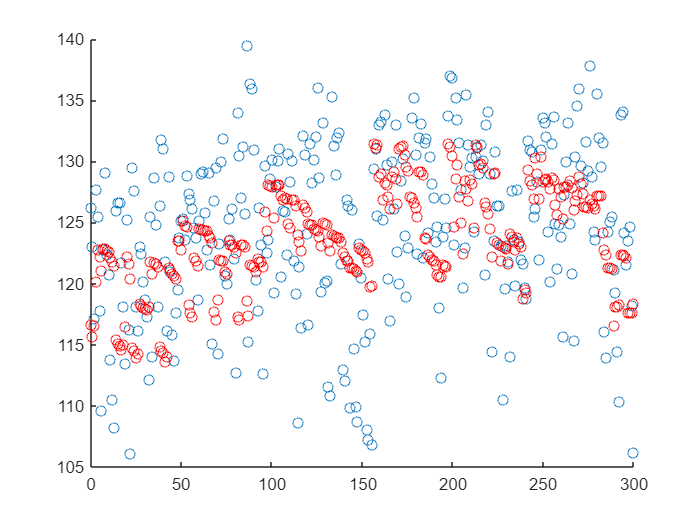

out = 1.5527e+03

[~, sorted_idx] = sort(fit0, 'ascend');
out=visucluster(cluster_pop{sorted_idx(1)},datatest,clusters)

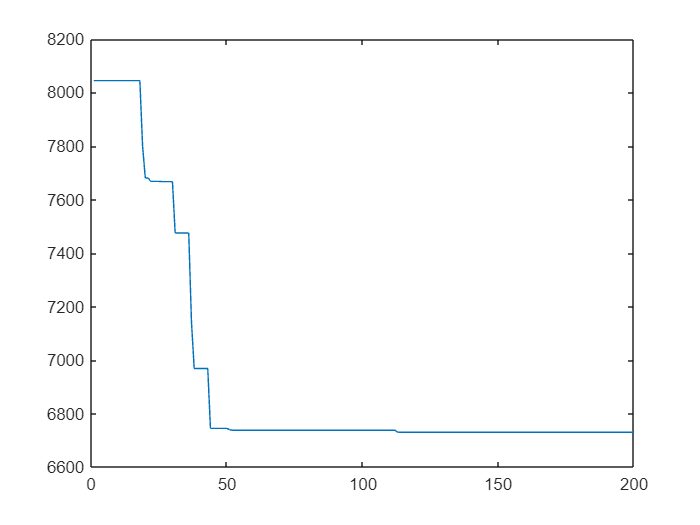

figure;
plot(bestfit)

here are all the functions used in the .mlx

% TSK initializations
%  real mf bounds : 0:20000; 0:25; 0:0.35; 0:75; 0:0.06; 
% syntetic mf : 0:1; 0:1; 0:1 /normalized value

function pop=initfcm(popsize,clusters)
    pop=cell(popsize,1);

    mfs=[];
    for i=1:popsize
        for k=1:max(size(clusters))
            rule_param=50*(rand(1,6)-0.5); % parameters between -10 and 10;
            rule_param(1,6)=120+100*(rand(1,1)-0.75); % constant between 70 and 170
            pop{i}=[pop{i}; mfs rule_param];
        end
    end


end





function pop=initcluster(popsize,clusters)
    pop=cell(popsize,1);
    % we will use a gaussian membership function based on the different
    % cluster centers and the optimization parameter will be the standard
    % deviation "std"

    % we then have a total of 5 std to tune plus 6 rule parameter per
    % cluster, totaling 11*13=143 parameters

    mfs=[];
    for i=1:popsize
        for k=1:max(size(clusters))
            mfs=0.05+0.15*rand(1,5); % initialize the std the between 0.05 and 0.1  for each cluster
            rule_param=20*(rand(1,6)-0.5); % parameters between -5 and 5;
            rule_param(1,6)=120+110*(rand(1,1)-0.5);
            pop{i}=[pop{i}; mfs rule_param];
        end
    end
end


%selection, mutation, reproduction
function [num_elites,pool] = selection(pop, fitness_vals, rate,popsize,e_rate)
    % popsize = length(pop);
    num_selected = round(rate * popsize);  
    num_elites = ceil(e_rate * popsize);
    [~, sorted_idx] = sort(fitness_vals, 'ascend');
    elites = pop(sorted_idx(1:num_elites));  % Preserve the best individuals
    if size(elites,1)~=1
        elites=elites';
    end
    % Tournament Selection (forces selection pressure)
    num_to_select = num_selected - num_elites;
    selected_individuals = cell(1, num_to_select);
    for i = 1:num_to_select
        % Pick 3 random individuals and select the best one
        candidates = randperm(popsize, 3);
        [~, best_idx] = min(fitness_vals(candidates));
        selected_individuals{i} = pop{candidates(best_idx)};
    end

    % Combine elites and selected individuals
    pool = [elites, selected_individuals];
end

function child = mutation(child, mutation_rate,clusters)
    if rand < mutation_rate
        if rand>0.66
            new_child=initfcm(1,clusters);
            child=new_child{1};
        else

            child=child.*(1+(0.4*rand(15,6)-0.5)); % up to +-20%
        end
    end
end

function new_pop = reproduction(pool, mutation_rate, popsize,num_elites,clusters)
    new_pop = cell(1, popsize);
    
    for i = 1:num_elites
        new_pop{i} = pool{i}; % Directly copy elite individuals
    end
    for i = num_elites+1:popsize
        parent1 = pool{randi(length(pool))}; %select parents
        parent2 = pool{randi(length(pool))};
        child=zeros(15,6);
        % we want to do crossover on each membership function by doing an
        % interpolation of the parents parameters and crossover on rules
        alpha=rand(1);
        beta=1-alpha;
        child=parent1*alpha+parent2*beta;
        % child(1:13,1:5)=parent1(1:13,1:5)*alpha + parent2(1:13,1:5)*beta;
        % child(1:8,:)= [parent1(1:8,:)];
        % child(9:15,:)=[parent2(9:15,:)];
        
        % Mutation
        child = mutation(child, mutation_rate,clusters);
        
        new_pop{i} = child;
    end
end
function f=fitfcm(chr,data,ccs)
    
    for ind=1:length(data)
        output=0;
        for k = 1:size(ccs,2)
            dist_ik = norm(data(ind,1:5) - ccs(k,:)) + 1e-6; % small value to avoid div by zero
            denom = 0;
            for j = 1:size(ccs,2)
                dist_ij = norm(data(ind,1:5) - ccs(j,:)) + 1e-6;
                denom = denom + (dist_ik / dist_ij)^(2/(2.5-1));
            end
            U_test(k) = 1 / denom;
            
            a = chr(k,1:5); % 5 coefficients
            b = chr(k,6);   % bias
            y_k = dot(a, data(ind,1:5)) + b;
            output = output + U_test(k) * y_k;
        end
        pred(ind,1) = output;
    end
    errors = abs(pred - data(:,6));
    % f = sum(errors)+10*max(errors);
    q = 0.95;
    J3 = quantile(errors, q);
    
    f = sum(errors) + 50*J3;


end

function mu=fcmeval(datatest, clusters, m)
    c = size(clusters, 1); % number of clusters
    n = size(datatest, 1); % number of data points
    U_test = zeros(c, n);
    output=0;
    for i = 1:n
        for k = 1:c
            dist_ik = norm(datatest(i,:) - clusters(k,:)) + 1e-6; % small value to avoid div by zero
            denom = 0;
            for j = 1:c
                dist_ij = norm(datatest(i,:) - clusters(j,:)) + 1e-6;
                denom = denom + (dist_ik / dist_ij)^(2/(m-1));
            end
            U_test(k,i) = 1 / denom;
        end
    end
end

function f=fitcm(chr,data,ccs)
   for ind=1:length(data)
       w=ones(max(size(ccs)),1);
        % let's compute the firing power of each rule
        for k=1:max(size(ccs))
            for input=1:5
                w(k)=w(k)*exp(-(data(ind,input)-ccs(k,input))^2/(2*chr(k,input)^2)); % based on gaussian membership 
            end
        end
        agregg=sum(w);
        output = 0;
        for k = 1:max(size(ccs))
            x_inputs = data(ind, 1:5);
            rule_params = chr(k, 6:11); % [a1...a5, b]
            rule_val = dot(rule_params(1:5), x_inputs) + rule_params(6);
            output = output + w(k) * rule_val;
        end
        pred(ind)=output/(agregg+10^(-10));
   end
   errors = abs(pred' - data(:,6));
   f = sum(errors);
end
% fitness function for 0 order tsk

function out=visu(chr, data,ccs)
    for ind=1:length(data)
       w=ones(max(size(ccs)),1);
        % let's compute the firing power of each rule
        for k=1:max(size(ccs))
            for input=1:5
                w(k)=w(k)*exp(-(data(ind,input)-ccs(k,input))^2/(2*chr(k,input)^2)); % based on gaussian membership 
            end
        end
        agregg=sum(w);
        output = 0;
        for k = 1:max(size(ccs))
            x_inputs = data(ind, 1:5);
            rule_params = chr(k, 6:11); % [a1...a5, b]
            rule_val = dot(rule_params(1:5), x_inputs) + rule_params(6);
            output = output + w(k) * rule_val;
        end
        pred(ind)=output/(agregg+10^(-10));
   end
   errors = abs(pred' - data(:,6));
   out = sum(errors);

    figure;
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),data(:,6))
    hold on 
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),pred,"red")

    % out=output;
end

function f=visucluster(chr,data,ccs)
    
    for ind=1:length(data)
        output=0;
        for k = 1:size(ccs,2)
            dist_ik = norm(data(ind,1:5) - ccs(k,:)) + 1e-6; % small value to avoid div by zero
            denom = 0;
            for j = 1:size(ccs,2)
                dist_ij = norm(data(ind,1:5) - ccs(j,:)) + 1e-6;
                denom = denom + (dist_ik / dist_ij)^(2/(2-1));
            end
            U_test(k) = 1 / denom;
            
            a = chr(k,1:5); % 5 coefficients
            b = chr(k,6);   % bias
            y_k = dot(a, data(ind,1:5)) + b;
            output = output + U_test(k) * y_k;
        end
        pred(ind,1) = output;
    end
    errors = abs(pred - data(:,6));
    f = sum(errors);

    figure;
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),data(:,6))
    hold on 
    scatter(linspace(0,length(data(:,6)),length(data(:,6))),pred,"red")
end
